# dinteg_msi

performs the integral double of a sampled signal with the MSI method.

## Syntax

pos=dinteg_msi(acc,freq)

## Description

`pos=dinteg_msi(acc,freq)` performs the integral double of a signal `acc` sampled at `freq` Hz. 		

The idea is to remove the non-zero medium value, maybe caused by sensor artifacts and uncertainties, prior to the first velocity integration. The mean value of the acceleration between two consecutive integration events was is subtracted, and a first integration is made to estimate the instantaneous velocity. Notice that forcing the acceleration to have a zero mean value is equivalent to assuming that the velocity is the same at the beginning and the end of the integration time.

				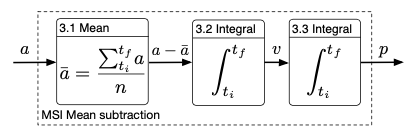

A mean subtraction was applied twice in the particular case where the final position is the same at the beginning and end of the integration period, but this case is not implemented. 

More information: 

Alvarez, J.C.; González, R.C.; Alvarez, D.; López, A.M.; Rodríguez-Uría, J. Multisensor approach to walking distance estimation with foot inertial sensing. *Conf. Proc. IEEE Eng. Med. Biol. Soc. ***2007**, *2007*, 5720–5723. 								 				

## Examples

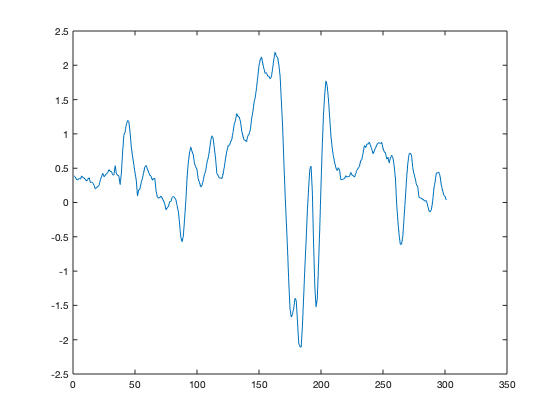

% cargamos datos de una acelerometro que sube y vuelve a la posicion de
% reposo:
filename='../simur_data/SAL.log';
datosxs=load(filename);
acc=datosxs(100:400,2)+9.8;
plot(acc);

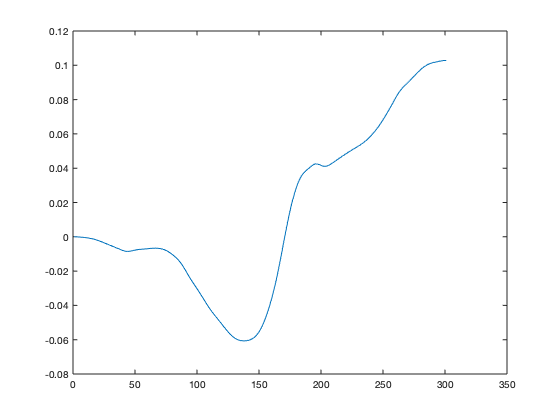

plot(dinteg_msi(acc,100));